%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%% TUE 5SMB0 System Identification
%%% Assignment 2022
%%% Authors: Jiaxuan Zhang, Yiting Li
%%%%%%%%%%%%%%%%%%%%%%%%%%%


## Data Generation

% [ u , y ] = assignment_sys_36(r)
clear all
close all 
clc


## Part 1: Understanding Saturation and Butterworth Filter

### 1.1

F.num = [ 0.505 , 1.01 , 0.505 ];
F.denom = [ 1 , 0.7478 , 0.2722 ];
F.sys = tf(F.num, F.denom, -1, 'Variable', 'z^-1')

F = struct with fields:
      num: [0.5050 1.0100 0.5050]
    denom: [1 0.7478 0.2722]
      sys: [1×1 tf]


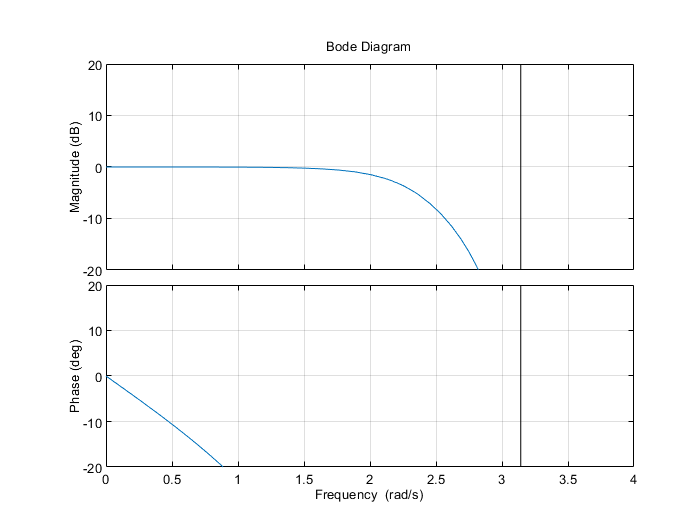


plotopts1 = bodeoptions;
plotopts1.FreqScale = 'linear';
plotopts1.XLim = {[0,4]};
plotopts1. Ylim = {[-20,20]};
plotopts1.Grid = 'on';
bode(F.sys, plotopts1)

% w = 2.1954 rad/s is the -3 db point, f = w/2/pi = 0.3494


### 1.2

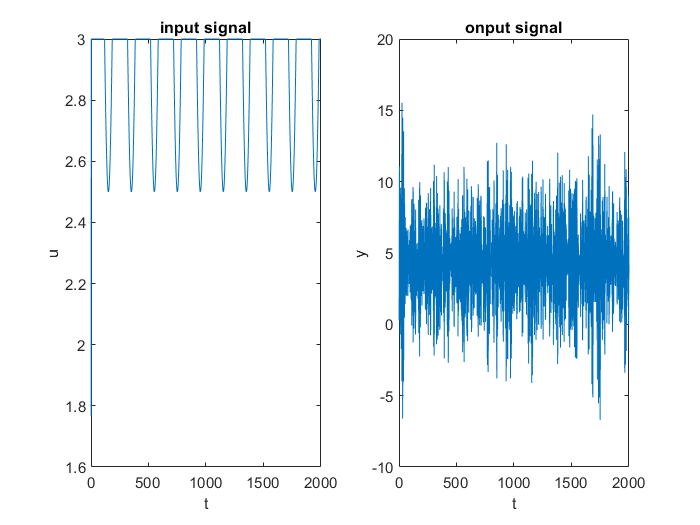

% nu = 100;
% previous_u = -100; 
% for mag=0:1:100
%     r = mag * ones(1,nu);
%     [u,y] = assignment_sys_36(r);
%     u(1)
%     previous_u
%     if (u(1) == previous_u)
%         fprintf("M is equal to %d", u(1));
%         break;
%     end
%     previous_u = u(1);
% end
% 
% % M is equal to 3

N = 2000;
f = 10;
offset = 3.5;
A = 1;

t = (0 : 1/N : 1)';
r = A * sin(2*pi*f*t) + offset; 

% r = ones([1, N]);
[u,y] = assignment_sys_36(r);


figure;
subplot(1, 2, 1)
plot(u)
xlabel("t");
ylabel("u");
title("input signal");

subplot(1, 2, 2)
plot(y)
xlabel("t");
ylabel("y");
title("onput signal");

% we now can know M is 3

## Part 2: Nonparametric identification

### 2.1. Nonparametric Identification

% system setup
N = 1024;
Ts = 1;
n_freq = 128;

% set the base frequency
w0 = 2/n_freq

w0 = 0.0156

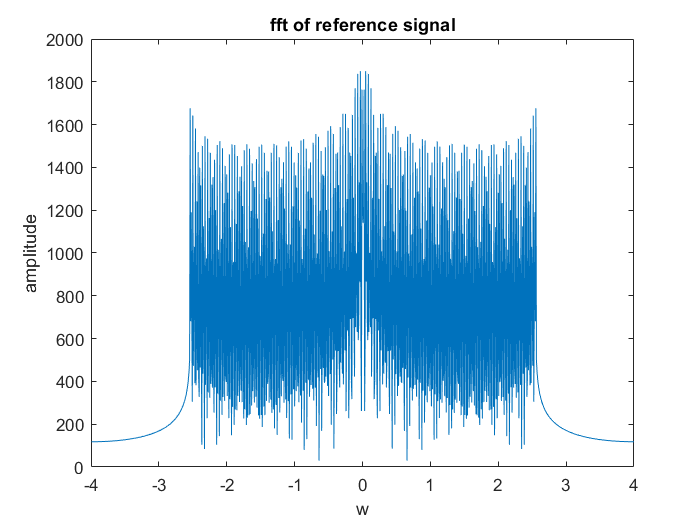


% generate reference signal
t = [0: 1: N-1]/Ts;
r=0;
for i = 1: 1: n_freq
    r = r + 3 * sin(w0*i*t) + offset;
end

% analysis reference spectrum
w = fft(r);
w = circshift(w, N/2);
wf = [-N/2+1: N/2]*w0/2;
plot(wf, abs(w))
xlabel("w"); ylabel("amplitude"); title("fft of reference signal");

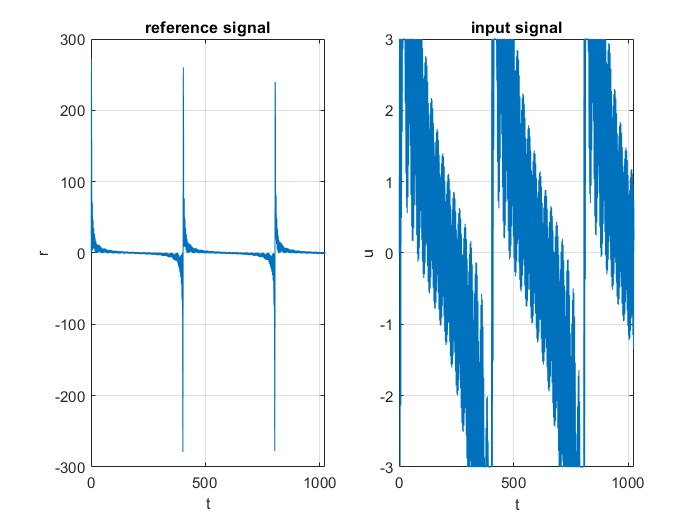


% plot reference signal
figure;
subplot(1, 2, 1)
plot(r)
grid on
xlabel("t"); ylabel("r"); title("reference signal");

% generate input-output
[u,y] = assignment_sys_36(r);
subplot(1, 2, 2)
plot(u)
grid on
xlabel("t"); ylabel("u"); title("input signal");


% ETFE identification
figure;
G_ETFE = etfe(iddata(y,u))

G_ETFE =
IDFRD model.
Contains Frequency Response Data for 1 output(s) and 1 input(s).
Response data is available at 128 frequency points, ranging from 0.02454 rad/s to 3.142 rad/s.
 
Sample time: 1 seconds
Output channels: 'y1'
Input channels: 'u1'
Status:                                  
Estimated using ETFE on time domain data.


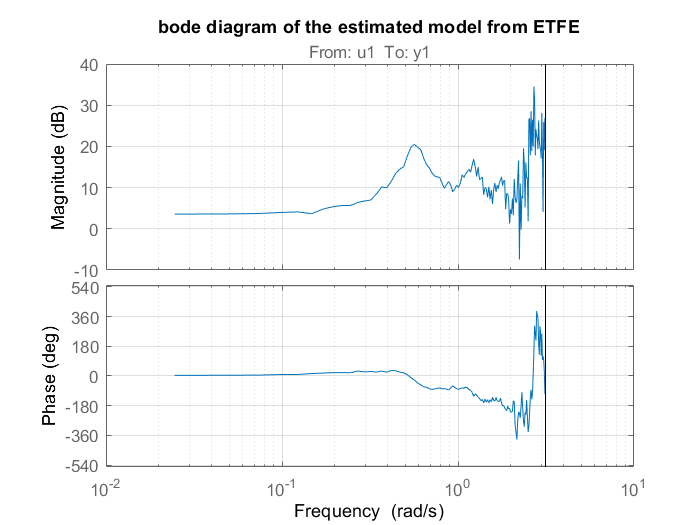

bode(G_ETFE)
grid on
title("bode diagram of the estimated model from ETFE");

### 2.3. Noise Spectrum Analysis

% Design a zero input, that is the output y will totally be noise signal
period = 128;
N = 1024;
r = 0*sin( [0: 1: N-1] * pi / period )

r =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


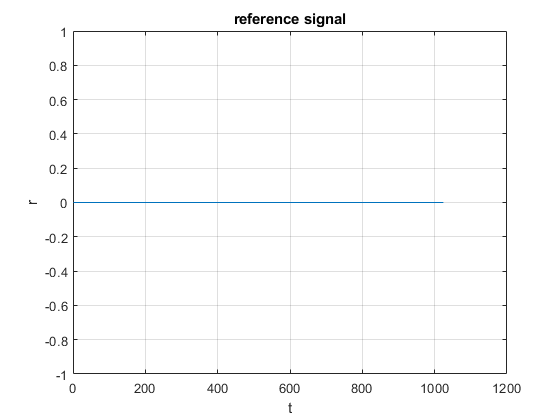



figure;
plot(r)
grid on
xlabel("t"); ylabel("r"); title("reference signal");

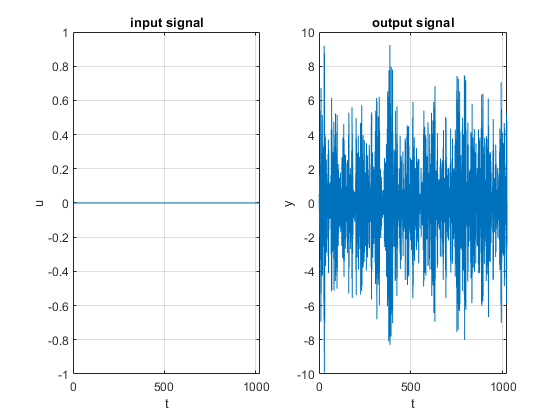


figure;
subplot(1, 2, 1)
[u,y] = assignment_sys_36(r);
plot(u)
grid on
xlabel("t"); ylabel("u"); title("input signal");

subplot(1, 2, 2)
plot(y)
grid on
xlabel("t"); ylabel("y"); title("output signal");

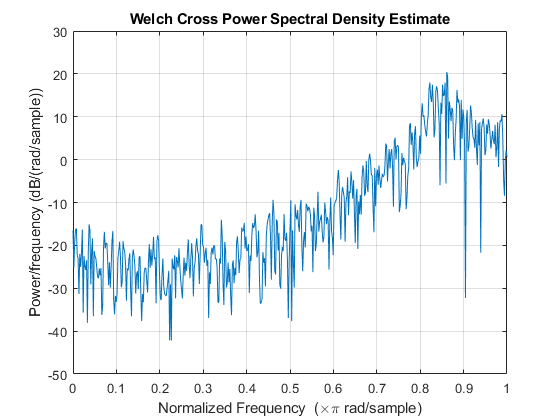


% analysis power specturm of noise signal
v = y;
figure;
[Pv, W] = cpsd(v, v, 1024);
cpsd(v, v, 1024)

## Part 3: Expreiment Design

### 3.1

% prefer PRBS

### 3.2

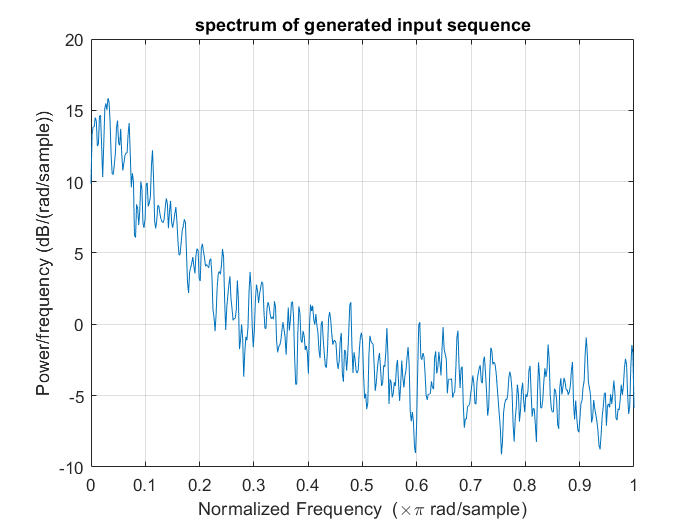

[r,P,w] = Generate_PRBS(0.9, 3000, 3, true);


% I think 0.83 is a good threshold


## Part 4: Parametric identification and validation

### 4.1 OE Model

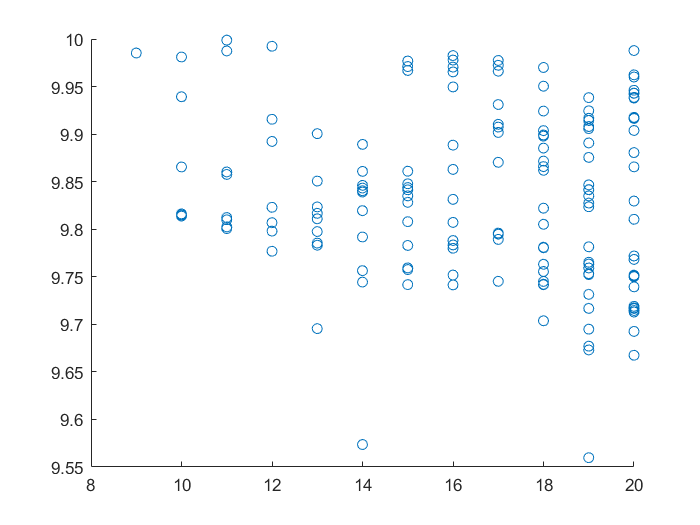

% Try OE Model

% divide the dataset into training set and validation set
[r,P,w] = Generate_PRBS(0.83, 3000, 3, false);
[u,y] = assignment_sys_36(r);
train_ratio = 0.7;
u_train = u([1: floor(train_ratio * length(u))]);
y_train = y([1: floor(train_ratio * length(y))]);
u_test = u([floor(train_ratio * length(u))+1: end]);
y_test = y([floor(train_ratio * length(y))+1: end]);

% prepare loop for order selection
order_upper = 20;
nb = 0; nf = 0; nk = 0;

OE.order.order_points = [];
OE.order.order_config = [];
OE.order.error = [];

for order_sum = 1: 1: order_upper
    
    for nb = 0: 1: order_sum
        
        for nf = 0: 1: order_sum - nb
            
            nk = order_sum - nb - nf;
            % for OE model, nk and nb cannot be zero at the same time
            if nk == 0 && nb == 0
                continue;
            end
            
            % identify a model
            temp_sys = oe(iddata(y_train, u_train), [nb, nf, nk]);
            % cost validate error
            temp_predict_error = pe(temp_sys, iddata(y_test, u_test), 1);
            temp_error = temp_predict_error.y' * temp_predict_error.y / length(y_test);
            
            % abort too abnormal result
            if temp_error > 10
                continue;
            end
            
            OE.order.order_points = [OE.order.order_points, order_sum];
            OE.order.order_config = [OE.order.order_config, [nb; nf; nk]];
            OE.order.error = [OE.order.error, temp_error];
            
        end
                  
    end
end
scatter(OE.order.order_points, OE.order.error);

% choose the optimal model
[M, I] = min(OE.order.error)

M = 9.5598

I = 108

OE.model_configuration = OE.order.order_config(:, I);
OE.model_order = OE.order.order_points(I);
OE.model_configuration

ans =      2
    16
     1


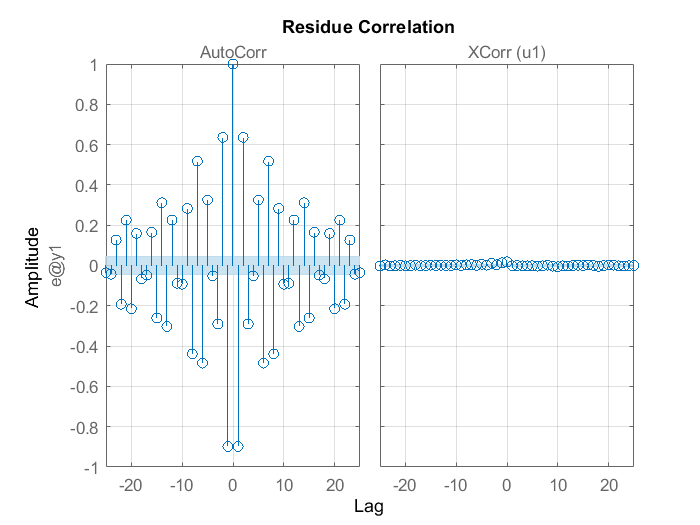

% generate input-output signal
[r,P,w] = Generate_PRBS(0.83, 3000, 3, false);
[u,y] = assignment_sys_36(r);

% identify an OE model
OE.sys = oe(iddata(y, u), [3,13,1]);

% residual test
OE.resid = resid(iddata(y,u), OE.sys);
figure
resid(iddata(y,u), OE.sys)
grid on;

### 4.1 ARX Model

% figure;
% plot(y)
% xlabel("t"); ylabel("y"); title("output signal");

% identify an ARX model
G_ARX = arx([y u], [10 9 1])

G_ARX =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                                                                        
                                                                                                                           
  A(z) = 1 + 1.62 z^-1 + 1.17 z^-2 + 0.8541 z^-3 + 0.8111 z^-4 + 0.6596 z^-5 + 0.896 z^-6 + 0.8908 z^-7 + 0.7819 z^        
                                                                                            -8 + 0.7509 z^-9 + 0.3745 z^-10
                                                                                                                           
  B(z) = 1.799 z^-1 + 4.915 z^-2 + 5.139 z^-3 + 2.532 z^-4 + 0.3481 z^-5 + 0.06197 z^-6 - 0.2725 z^-7 + 0.1707 z^-8        
                                                                                                                           
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   na=10   nb=8   nk=1
   Number of free coefficients: 18
 

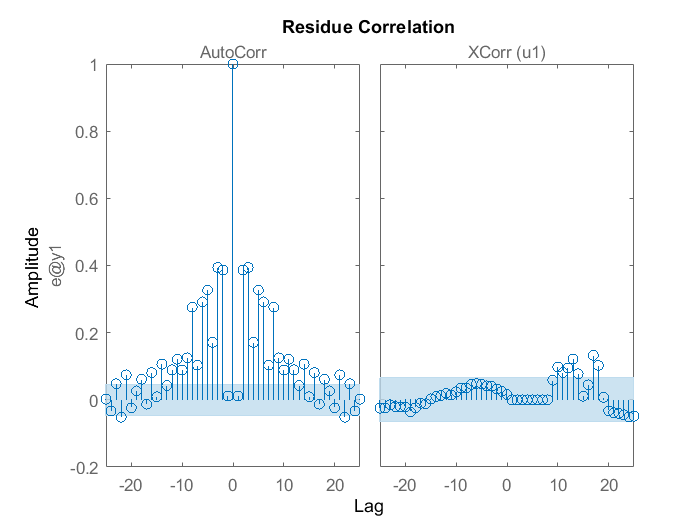

% good 10 9 1

% do the residual test
resid([y u], G_ARX)



% Using the systemIdentification Toolbox 
% Using the r to generate u and y, then import these two time domain data
% into the Toolbox
% Using the polynomial model estimation with ARX model
% In the Polynomial Model screen

## Part 5: Experimental verification of variance estimates

### 5.1. Variance Esitmate

% using the same r to generate the u and y, set the loop number as 100
Loop = 100;

[r,P,w] = Generate_PRBS(0.83, 1000, 3, false);

% using the parameter obtained from previous section
nb = 4; nf = 14; nk = 1;
result = zeros([Loop, nb+nk+nf-1], 'double');

for i = 1:Loop
    [u,y] = assignment_sys_36(r);
    G_OE = oe([y u], [nb nf nk]);
    F = G_OE.Structure.F.Value(2:1:end);
    B = G_OE.Structure.B.Value(2:1:end);
    result(i,:) = [B F];
end
clear B F i
% the storing fromat is B(1x4) and F(1x13) in one raw
result

result =     1.8046    2.2775   -1.0997   -2.6297    0.1924   -0.8086    0.1720    0.1621   -0.3601    0.5090   -0.2029   -0.1201    0.1933   -0.4588   -0.2110    0.2929   -0.1640    0.0334
    1.8867    1.5392    0.0756   -1.1565   -0.1556    0.2073   -0.1833    0.4546   -0.2436    0.5847   -0.2792    0.4673   -0.2879    0.1990   -0.4082    0.3212   -0.1453    0.0253
    1.6587    0.9124   -2.1882   -0.2880   -0.8174    0.0786    0.0254    0.0414   -0.2267    0.5346   -0.6440    0.5362   -0.4408    0.0150   -0.1508    0.2238   -0.1586    0.0459
    1.7052    2.8255    0.2514   -0.7995    0.3832   -0.1294    0.3454    0.1938    0.1306    0.3907    0.1746    0.1534    0.1852   -0.0603   -0.2296    0.2134   -0.0823   -0.0049
    1.7626    1.2547   -1.2176   -1.7920   -0.4470   -0.0405   -0.3688    0.4340   -0.4541    0.5237   -0.4565    0.3531   -0.4467    0.1555   -0.5069    0.4200   -0.2003    0.0398
    1.8754    0.5336   -0.6949   -1.5901   -0.6990    0.3210   -0.4977    0.3654   -0.

### 5.2

### 5.3. Variance Comparison

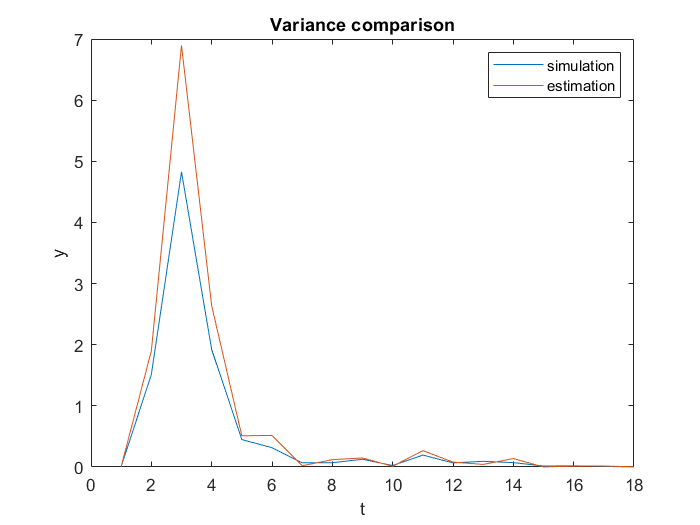

cov = getcov(G_OE);

cov_est = diag(cov)';

cov_sim = zeros([2, (nb+nk+nf-1)], 'double');
for k = 1:(nb+nk+nf-1)
     
    cov_sim(1, k) = mean(result(:, k));
    cov_sim(2, k) = var(result(:, k));
end

% figure;
% plot(result(:,k))
% xlabel("t"); ylabel("y"); title("output signal");


figure;
plot(cov_sim(2,:))
hold on
plot(cov_est)
legend('simulation','estimation')
xlabel("t"); ylabel("y"); title("Variance comparison");


clear k

### 5.4

result_54 = zeros([Loop, nb+nk+nf-1], 'double');

% for i = 1:Loop
%     [u,y] = assignment_sys_36(r);
%     G_OE = oe([y u], [nb nf nk]);
%     F_init = G_OE.Structure.F.Value;
%     B_init = G_OE.Structure.B.Value;
%     M_init = idpoly([], B_init, [], [], F_init);
%     M_oe = oe([y u], M_init);
%     F = G_OE.Structure.F.Value(2:1:end);
%     B = G_OE.Structure.B.Value(2:1:end);
%     result_54(i,:) = [B F];
% end

OEopt = oeOptions;
OEopt.SearchOptions.Tolerance = 10e-6;

for i = 1:Loop
    
    % Generate new data
    [u,y] = assignment_sys_36(r);
    
    if i == 0
        
        % generate an initial OE model
        M_oe = oe([y,u], [nb, nf, nk], OEopt);
        
    else
        % update starting point
        B_init = median(result_54([1: 1: i], [1: 1: nb]),1);
        F_init = median(result_54([1: 1: i], [nb+1: 1: end]),1);
        M_init = idpoly([], [0, B_init], [], [], [1, F_init]);
        
        % start OE model identification from the starting point
        M_oe = oe([y u], M_init, OEopt);
    end
    
    % record the parameter
    F = G_OE.Structure.F.Value(2:1:end);
    B = G_OE.Structure.B.Value(2:1:end);
    result_54(i,:) = [B F];
           
end
    

clear B F i
% the storing fromat is B(1x4) and F(1x13) in one raw
result_54

result_54 =     1.8621    0.4681   -0.0235   -0.3034   -0.7393    0.7015   -0.1314   -0.1219    0.6181   -0.3082    0.2138    0.3909   -0.5527    0.5609   -0.5414    0.3804   -0.1810    0.0409
    1.8621    0.4681   -0.0235   -0.3034   -0.7393    0.7015   -0.1314   -0.1219    0.6181   -0.3082    0.2138    0.3909   -0.5527    0.5609   -0.5414    0.3804   -0.1810    0.0409
    1.8621    0.4681   -0.0235   -0.3034   -0.7393    0.7015   -0.1314   -0.1219    0.6181   -0.3082    0.2138    0.3909   -0.5527    0.5609   -0.5414    0.3804   -0.1810    0.0409
    1.8621    0.4681   -0.0235   -0.3034   -0.7393    0.7015   -0.1314   -0.1219    0.6181   -0.3082    0.2138    0.3909   -0.5527    0.5609   -0.5414    0.3804   -0.1810    0.0409
    1.8621    0.4681   -0.0235   -0.3034   -0.7393    0.7015   -0.1314   -0.1219    0.6181   -0.3082    0.2138    0.3909   -0.5527    0.5609   -0.5414    0.3804   -0.1810    0.0409
    1.8621    0.4681   -0.0235   -0.3034   -0.7393    0.7015   -0.1314   -0.1219   

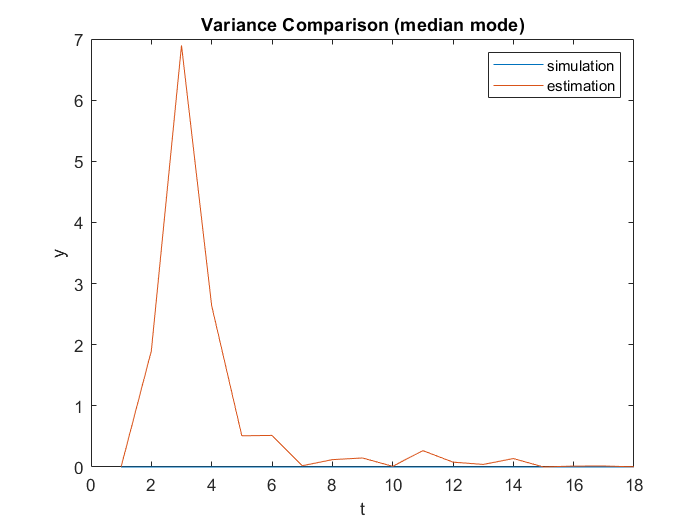

cov_sim_54 = zeros([2, (nb+nk+nf-1)], 'double');
for k = 1:(nb+nk+nf-1)
     
    cov_sim_54(1, k) = mean(result_54(:, k));
    cov_sim_54(2, k) = var(result_54(:, k));
end

% figure;
% plot(result_54(:,k))
% xlabel("t"); ylabel("y"); title("output signal");
% 

figure;
plot(cov_sim_54(2,:))
hold on
plot(cov_est)
legend('simulation','estimation')
xlabel("t"); ylabel("y"); title("Variance Comparison (median mode)");


clear k

## Part 6: Estimation of a Box Jenkins model for minimum variance

### 6.1. Identify an BJ model

nb = 3;
nf = 13;
nc = 3;
nd = 5;
nk = 1;

% identify an BJ model
BJ.sys = bj(iddata(y,u), [nb, nc, nd, nf, nk]);

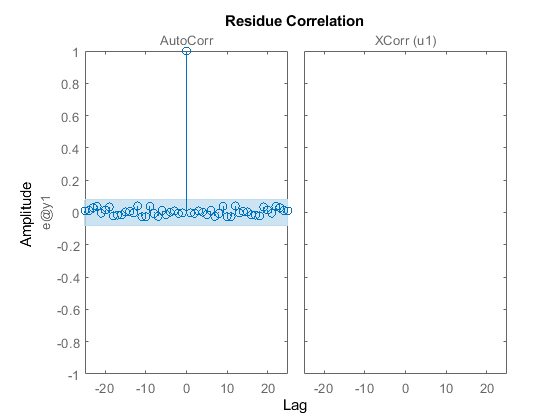


% resid test
figure;
resid(iddata(y,u), BJ.sys)

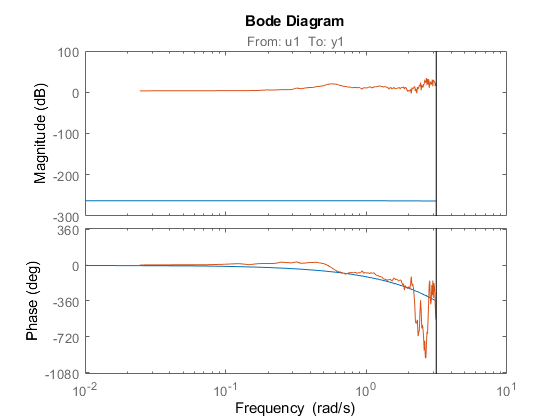


% bode graph of ETFE and identifed BJ model
figure;
bode(BJ.sys, G_ETFE)

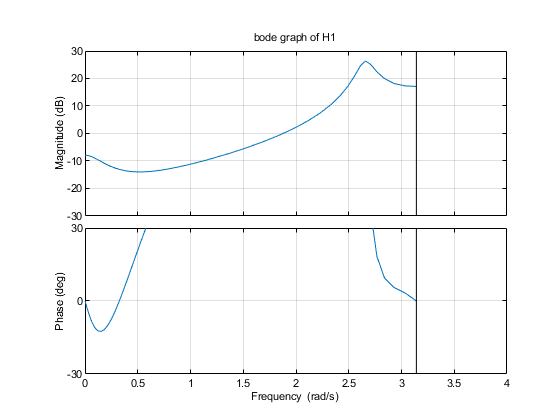


% TODO: bode graph of the noise signal power spectrum and identified H in the
% BJ model

plotopts2 = bodeoptions;
plotopts2.FreqScale = 'linear';
plotopts2.XLim = {[0,4]};
plotopts2. Ylim = {[-30,30]};
plotopts2.Grid = 'on';
% bode(tf(BJ.sys.C, BJ.sys.D, -1, 'Variable', 'z^-1'))
H = tf(BJ.sys.C, BJ.sys.D, -1, 'Variable', 'z^-1');
% G = tf(BJ.sys.C, BJ.sys.D, -1, 'Variable', 'z^-1');
bode(H,plotopts2)
grid on;
title('bode graph of H1');

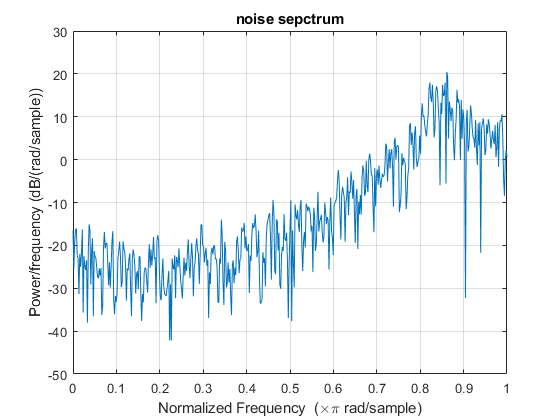

% G1= tf(BJ.sys.C, BJ.sys.D, -1);
% v = filter(BJ.sys.B, BJ.sys.F, u);
% v = filter(BJ.sys.D, BJ.sys.C, (y-v));
cpsd(v, v, 1024);
title('noise sepctrum')

### 6.2. compute the variance

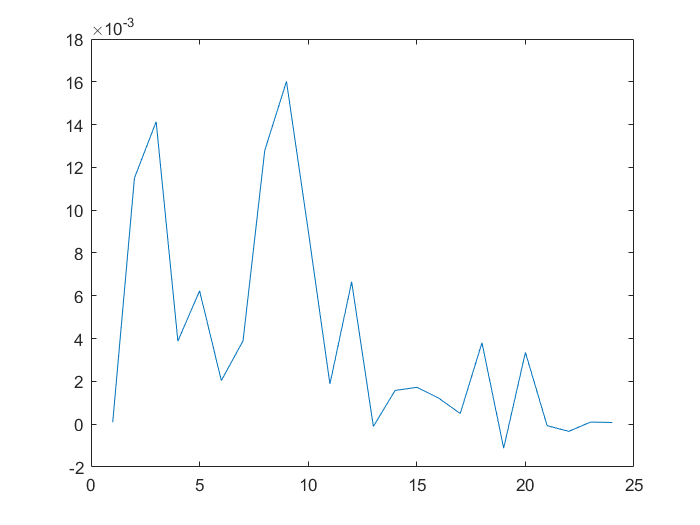

cov = getcov(BJ.sys);
figure 
plot(cov(2,:))

## Function Used

function [r,P,w] = Generate_PRBS(probability, N, mag, plt_flag)
%%%%%%%%%%%%%%%
%% generate PRBS based on:
%% u(t) = u(t-1) with probability p
%% u(t) = -u(t-1) with probability 1-p
%% and may plot spectral density based on setting
%% input: 
%%    P : prbability
%%    N : total input points
%%    mag: output magnitude
%%    plt_flg: if true, plot sepctral density
%% output:
%%    u : generated input sequence
%%    P : spectral density of P
%%    w : spectral density points
%%%%%%%%%%%%%%%%


    % determine the initial entry of u, that is u(1)
    if rand(1,1)>=0.5
        r(1) = mag;
    else
        r(1) = -mag;
    end
    
    % generate sequence
    for i = 2:1:N
        if rand(1,1) <= probability
            r(i) = r(i-1);
        else
            r(i) = -r(i-1);
        end
    end
    
    % get spectrum of generated input sequence
    [P,w] = cpsd(r,r,N);
    
    if (plt_flag == true)
        cpsd(r, r);
        title('spectrum of generated input sequence')
    end
    
end